Task 1: Download and load the data

%% Load images
clear; close; clc;

image_list = dir("C:/Users/princ/OneDrive/Documents/MATLAB/ComputerVision/Week3/cells/images/*.png");
mask_list = dir("C:/Users/princ/OneDrive/Documents/MATLAB/ComputerVision/Week3/cells/masks/*.png");

X = {}; Y = {};

for i = 1:length(image_list)

    ifname = image_list(i).name;
    gfname = mask_list(i).name;
    X{i} = imread(strcat("C:/Users/princ/OneDrive/Documents/MATLAB/ComputerVision/Week3/cells/images/", ifname));
    Y{i} = imread(strcat("C:/Users/princ/OneDrive/Documents/MATLAB/ComputerVision/Week3/cells/masks/", gfname));
end

idx = 1; % <-- change this to select a different image
I = X{idx}; Yt = logical(Y{idx}(:,:,1));
I_gray = rgb2gray(I);

Task 2: Segmenting cells

threshold = graythresh(I_gray); %otsuthresh %adaptthresh
segmented = imbinarize(I_gray,threshold);
segmented = ~segmented

segmented = 1200×1600 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

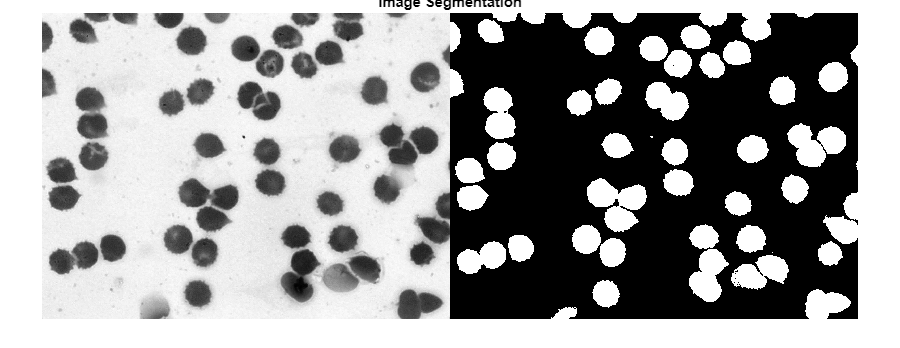

imshowpair(I_gray,segmented,'montage')
title('Image Segmentation')

Task 3 & 4: Qualitative Evaluation

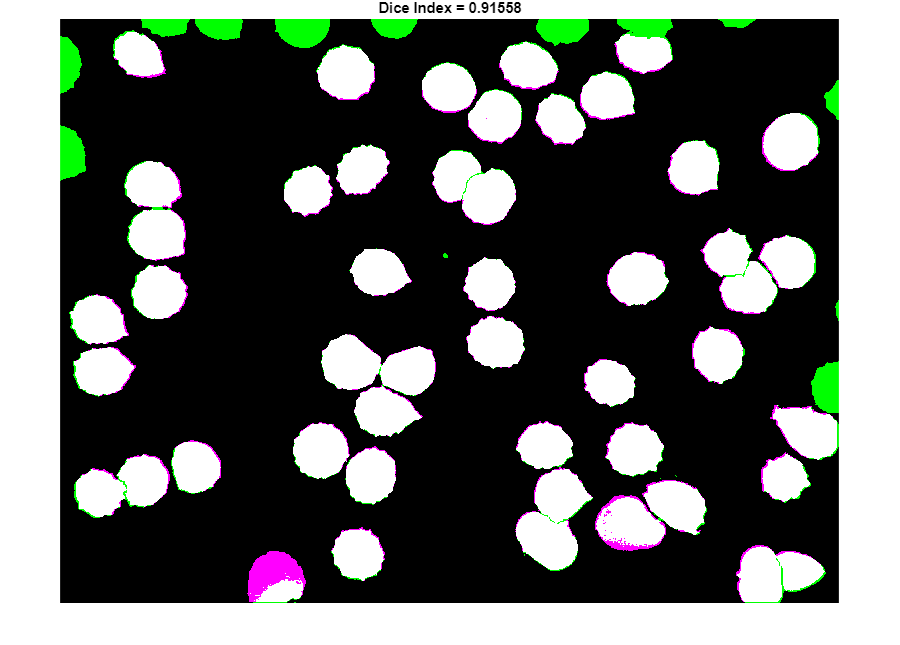

similarity = dice(segmented, Yt);

figure
imshowpair(segmented, Yt)
title(['Dice Index = ' num2str(similarity)])

Task 5: Calculating statistics

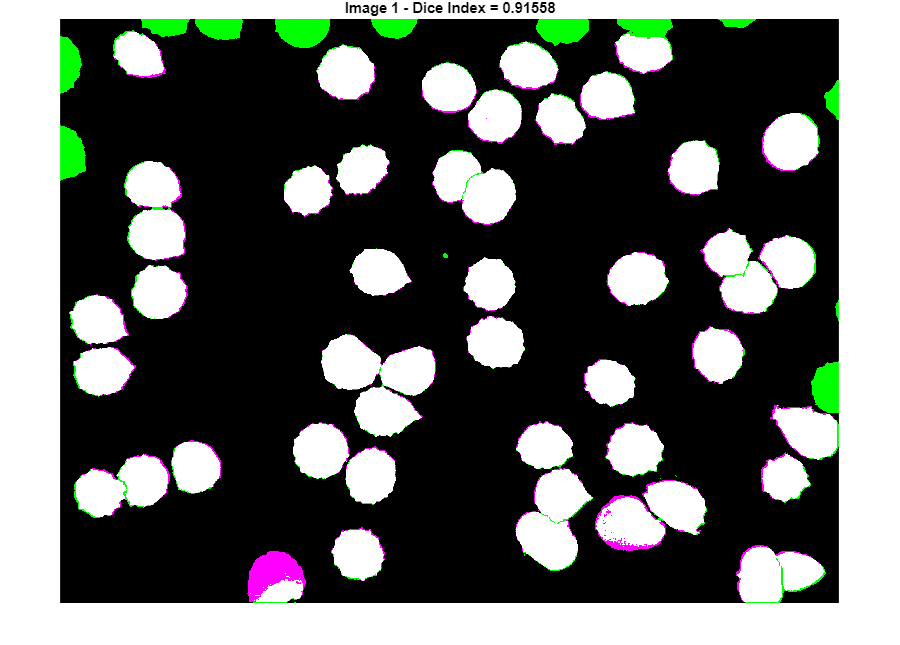

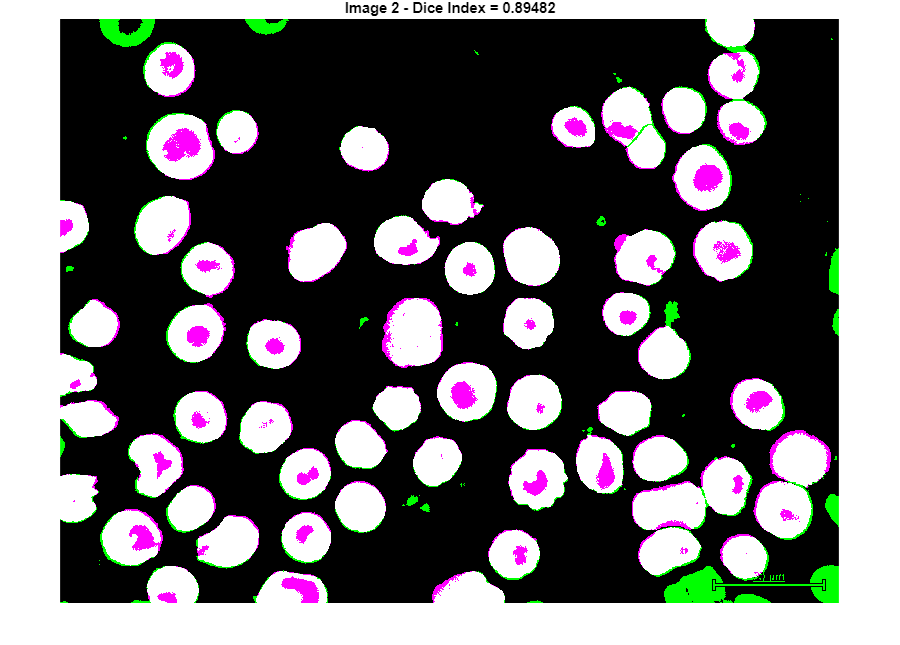

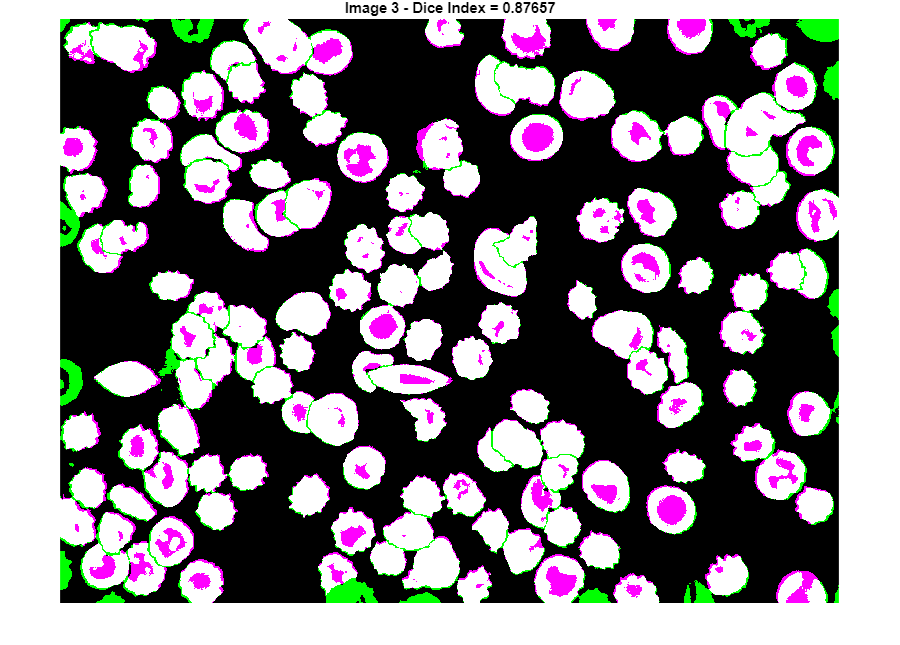

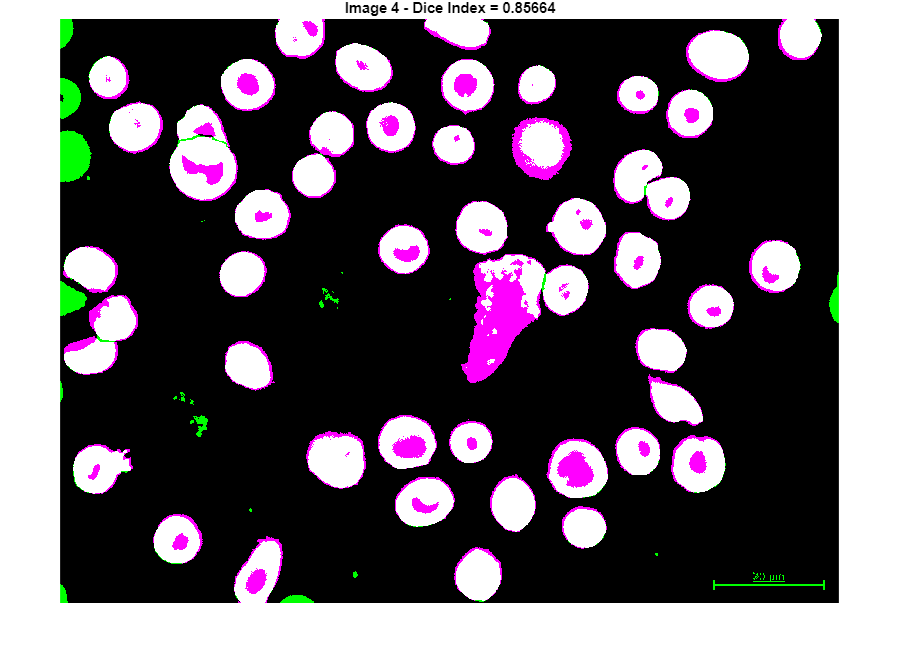

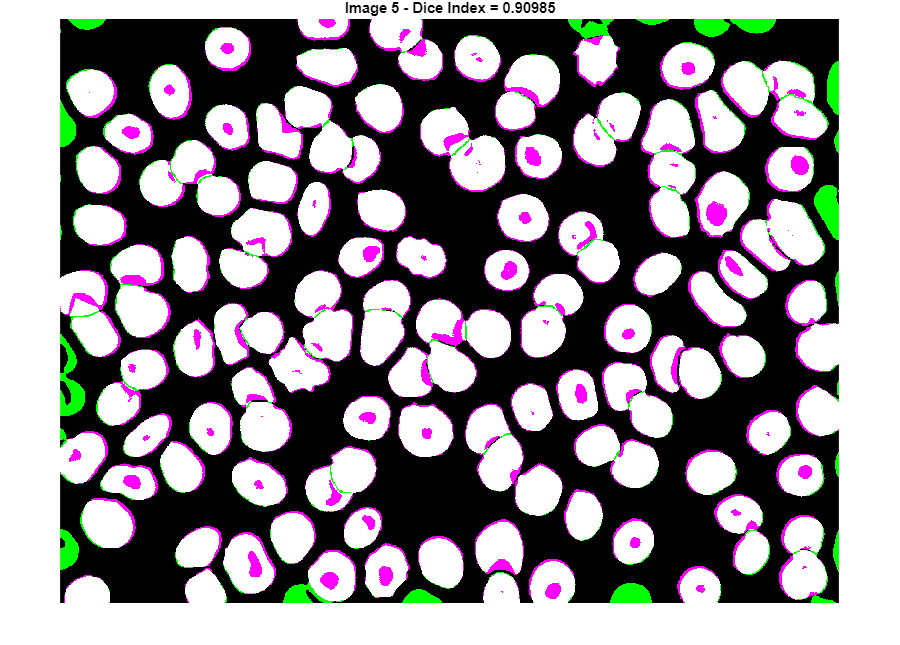

% Initialize array to store DSC values
dsc_values = zeros(1, length(X));

% Loop through all images
for idx = 1:length(X)
    I = X{idx}; 
    Yt = logical(Y{idx}(:,:,1)); % Ensures the ground truth is in logical format
    I_gray = rgb2gray(I);

    % Segmenting cells using Otsu's method
    threshold = graythresh(I_gray); 
    segmented = imbinarize(I_gray, threshold);
    segmented = ~segmented;

    % Dice Similarity Coefficient for the current image
    dsc_values(idx) = dice(segmented, Yt);
    
    % Results for each image
    figure;
    imshowpair(segmented, Yt);
    title(['Image ', num2str(idx), ' - Dice Index = ', num2str(dsc_values(idx))]);
end


% Mean and standard deviation of DSC values
mean_dsc = mean(dsc_values);
std_dsc = std(dsc_values);

% Overall results
fprintf('Mean DSC: %.4f\n', mean_dsc);

Mean DSC: 0.8907


fprintf('Standard Deviation of DSC: %.4f\n', std_dsc);

Standard Deviation of DSC: 0.0243
